clear
data=readtable("dataClean.csv")

data = 8760×12 table
           tstamp             AC      tou_id     DC     weekDay    Sat    Sun    wrkHr    dayTime    Off_Peak    Peak    Standard
    ____________________    ______    ______    ____    _______    ___    ___    _____    _______    ________    ____    ________

    01-Jan-2022 00:00:00    96.855      1       52.2       0        1      0       0         0          1         0         0    
    01-Jan-2022 01:00:00    97.053      1         52       0        1      0       0         0          1         0         0    
    01-Jan-2022 02:00:00    97.229      1       52

data = 8760×2 table
    Wind_Out    PV_Out
    ________    ______

     61.478          0
     36.949          0
     42.087          0
     84.377          0
     167.44          0
     239.07          0
     436.85     26.393
     497.53     69.626
     499.37     115.05
        500     188.93
     464.86     74.453
     496.45     65.394
     423.15     221.67
     338.31     202.77
        341     106.29
     334.64     66.523



numObservations = size(data);
percentSplit = 0.7;

idxTrain = 1:floor(percentSplit*numObservations);
X = data(idxTrain,:);



SARIMA_AC = arima('Constant',NaN,'D',0,'MALags',1,'ARLags',1,'Seasonality',24,'SARLags',24,'SMALags',24,'Distribution','Gaussian');
SARIMA_AC = estimate(SARIMA_AC,X.AC,'Display','off')

SARIMA_AC =   arima with properties:

     Description: "ARIMA(1,0,1) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 49
               D: 0
               Q: 25
        Constant: -0.061379
              AR: {0.82302} at lag [1]
             SAR: {-0.0161366} at lag [24]
              MA: {-0.0651891} at lag [1]
             SMA: {-0.961787} at lag [24]
     Seasonality: 24
            Beta: [1×0]
        Variance: 11718


SARIMA_DC = arima('Constant',NaN,'D',0,'ARLags',1,'Seasonality',24,'SARLags',24,'Distribution','Gaussian');
SARIMA_DC = estimate(SARIMA_DC,X.DC,'Display','off')

SARIMA_DC =   arima with properties:

     Description: "ARIMA(1,0,0) Model Seasonally Integrated with Seasonal AR(24) (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 49
               D: 0
               Q: 0
        Constant: 0.0813837
              AR: {0.740915} at lag [1]
             SAR: {-0.477289} at lag [24]
              MA: {}
             SMA: {}
     Seasonality: 24
            Beta: [1×0]
        Variance: 1910.98

nForecast = 24

nForecast = 24

load = zeros(length(data.DC),1)

load =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


load_preds = zeros(length(data.DC), nForecast);
for j = 76:(length(data.AC(:))-24)
    offset = j;
    [Y_ac, ] = forecast(SARIMA_AC, nForecast, data.AC(1:offset-1) );
    [Y_dc, ] = forecast(SARIMA_DC, nForecast, data.DC(1:offset-1) );
    load(j) = data.AC(offset-1) + data.DC(offset-1);
    load_preds(j,:) = Y_ac + Y_dc;
end




load_actual_test = data.AC + data.DC;

if load_actual_test(75) == load(76) 
    display("you were right muthafucka")
else
    display(load_actual_test(75:77))
    display(load(75:77))
end

    "you were right muthafucka"





for i = 1:75 
    load_preds(i,:) = load_actual_test(i:i+23)';
end



%load_preds = csvread("load_preds.csv");
load_preds=load_preds'

load_preds =    61.4782   36.9486   42.0871   84.3766  167.4359  239.0695  463.2395  567.1529  614.4181  688.9339  539.3126  561.8449  644.8179  541.0737  447.2893  401.1608  450.3837  518.8797  501.8238  511.1599  393.3147  494.4162  494.6100  490.9542  500.0000  370.5067  477.7244  500.0000  492.9503  171.0097   49.5520  106.6591  328.8133  336.7946  447.4057  776.7933  771.8082  695.3205  779.0492  781.9561  661.4822  610.8888  474.5448  474.7839  193.1342   90.6107   63.7015   71.4024    9.0732   11.7034
   36.9486   42.0871   84.3766  167.4359  239.0695  463.2395  567.1529  614.4181  688.9339  539.3126  561.8449  644.8179  541.0737  447.2893  401.1608  450.3837  518.8797  501.8238  511.1599  393.3147  494.4162  494.6100  490.9542  500.0000  370.5067  477.7244  500.0000  492.9503  171.0097   49.5520  106.6591  328.8133  336.7946  447.4057  776.7933  771.8082  695.3205  779.0492  781.9561  661.4822  610.8888  474.5448  474.7839  193.1342   90.6107   63.7015   71.4024    9.0732   11.

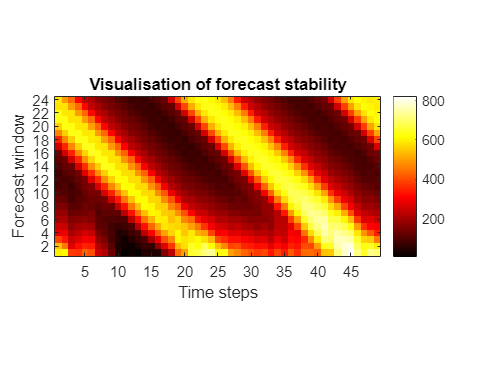


% Display the array as an image
imagesc(load_preds(:,7000:7048));

% Use inverted gray colormap (so higher values are darker)
colormap(hot);

% Adjust the appearance
axis equal tight;  % Makes pixels square, removes axis, and fits the display
colorbar;  % Shows a colorbar for reference
xticks(0:5:size(load_preds, 2));  % Here 5 is the step for ticks along x-axis, adjust as needed
yticks(0:2:24);  % Here 10 is the step for ticks along y-axis, adjust as needed
ylabel('Forecast window');  % X-axis label
xlabel('Time steps');  % Y-axis label
title('Visualisation of forecast stability')
set(gca, 'YDir', 'normal');


csvwrite("gen_preds.csv",load_preds)

test = csvread("gen_preds.csv")

test =    61.4780   36.9490   42.0870   84.3770  167.4400  239.0700  463.2400  567.1500  614.4200  688.9300  539.3100  561.8400  644.8200  541.0700  447.2900  401.1600  450.3800  518.8800  501.8200  511.1600  393.3100  494.4200  494.6100  490.9500
   36.9490   42.0870   84.3770  167.4400  239.0700  463.2400  567.1500  614.4200  688.9300  539.3100  561.8400  644.8200  541.0700  447.2900  401.1600  450.3800  518.8800  501.8200  511.1600  393.3100  494.4200  494.6100  490.9500  500.0000
   42.0870   84.3770  167.4400  239.0700  463.2400  567.1500  614.4200  688.9300  539.3100  561.8400  644.8200  541.0700  447.2900  401.1600  450.3800  518.8800  501.8200  511.1600  393.3100  494.4200  494.6100  490.9500  500.0000  370.5100
   84.3770  167.4400  239.0700  463.2400  567.1500  614.4200  688.9300  539.3100  561.8400  644.8200  541.0700  447.2900  401.1600  450.3800  518.8800  501.8200  511.1600  393.3100  494.4200  494.6100  490.9500  500.0000  370.5100  477.7200
  167.4400  239.0700  463.240